% syms s t;
s = tf('s');
SN = 38113544;
student_num = [3 8 1 1 3 5 4 4];
sn_A = student_num(1) + 10;
sn_B = student_num(2) + 10;
sn_C = student_num(3) + 10;
sn_D = student_num(4) + 10;
sn_E = student_num(5) + 10;
sn_F = student_num(6) + 10;
sn_G = student_num(7) + 10;
sn_H = student_num(8) + 10;

rad2deg = 180/pi;
deg2rad = pi/180;       

% state space need to knows:

% states are always based on energy stored
% - capacitors depend on voltage
% - inductors depend on current
% - mass depends on velocity


% Motor Specs
V_nom = 12 % nominal voltage V

V_nom = 12

I_noload = (250 + (10*sn_A))*10^-3 % no load current A

I_noload = 0.3800

R_terminal = 0.2 % Ohm

R_terminal = 0.2000

L_terminal = 0.5*10^-3 % H

L_terminal = 5.0000e-04

J_motor = (100+sn_B)*10^-7 % kg*m^2

J_motor = 1.1800e-05

K_speed = 600 + (10*sn_C) % rpm/v

K_speed = 710

K_torque = 60/(K_speed*2*pi) % Nm/rad*A (Torque Constant)

K_torque = 0.0134


back_emf = V_nom-I_noload*R_terminal

back_emf = 11.9240

w_noload = back_emf/K_torque 

w_noload = 886.5616

B_motor = I_noload*K_torque/w_noload

B_motor = 5.7648e-06


% Micro-controller Specs
CF = 100+(10*sn_A);

% Load Specs
J_load = (sn_A+sn_B+sn_C)*10^-6 % Nms^2/rad 

J_load = 4.2000e-05

B_load = (sn_D+sn_E+sn_F)*10^-6 % Nms^2/rad

B_load = 3.9000e-05

K1_load = 2*10^-3 % Nm/rad

K1_load = 0.0020

K2_load = 3*sn_G*10^-3 % Nm/rad

K2_load = 0.0420


% Amplifier Specs
DC_gain = sn_B % V/V

DC_gain = 18

omega_natural = sn_A*sn_B*sn_C*sn_D % rad/s

omega_natural = 28314

zeta = sn_D/10

zeta = 1.1000

% Load Block

% -R/L needs to be on the voltage term,
% -Km/L needs to be on the motor speed term (back EMF)

% idotdot = V/L - R*i/L - K_torque*w/L
% motortau = Km*i

J = J_motor+J_load

J = 5.3800e-05

K = K1_load*K2_load/(K1_load+K2_load)

K = 0.0019


G_A = [-R_terminal/L_terminal, -K_torque/L_terminal, 0 ; % i
        K_torque/J  ,   -(B_motor+B_load)/J  , -K/J, ; % omega
        0  ,   1 , 0 ] % theta

G_A =  -400.0000  -26.8994         0
  249.9947   -0.8321  -35.4850
         0    1.0000         0


   

G_B = [1/L_terminal, 0, 0].'; 

%yhat = [thetam thetal wm taukg taukf taukl]

G_C = [0, 0, 1];
G_D = [0].';

% get tf 
[ss_tf_num, ss_tf_den] = ss2tf(G_A, G_B, G_C, G_D);

theta_tf = tf(ss_tf_num(1,:), ss_tf_den);


% Amp Block
amp_tf = (DC_gain*omega_natural^2)...
         /(s^2+2*zeta*omega_natural*s+omega_natural^2) 

amp_tf =
 
           1.443e10
  ---------------------------
  s^2 + 6.229e04 s + 8.017e08
 
Continuous-time transfer function.




% Microcontroller Block
mcu_tf = 2*CF/(s+2*CF)

mcu_tf =
 
    460
  -------
  s + 460
 
Continuous-time transfer function.




% Open-loop GH
G = amp_tf*theta_tf

G =
 
                                  7.215e15
  ------------------------------------------------------------------------
  s^5 + 6.269e04 s^4 + 8.267e08 s^3 + 3.218e11 s^2 + 5.687e12 s + 1.138e13
 
Continuous-time transfer function.



H = mcu_tf

H =
 
    460
  -------
  s + 460
 
Continuous-time transfer function.




GH = G*H;

checkGH

 
Using SN: 38113544
 
Using GH:
*** Expect run-time error if GH not LTI object ***

GH =
 
                                         3.319e18
  --------------------------------------------------------------------------------------
  s^6 + 6.315e04 s^5 + 8.555e08 s^4 + 7.02e11 s^3 + 1.537e14 s^2 + 2.628e15 s + 5.234e15
 
Continuous-time transfer function.

+------------+
| GH Correct |
+------------+


% PID Design
% marginally stable reference

kappa = margin(G*H)

kappa = 0.1682

p = 2*CF

p = 460


% iterate setting z_start to PxO/10 until the error is less than 2 decimal

[~, ~, PxO, Wcg] = margin(kappa*G*H)

PxO = 61.1875

Wcg = 61.1875

z_start = PxO/10

z_start = 6.1187

z_last = z_start

z_last = 6.1187


% do below but in loop

% D_start = ll_dynamics(p, z_start, z_start)
% 
% [~, ~, PxO, Wcg] = margin(1*D_start*G*H)
% z_start = PxO/10

err = 100;
i = 0;

while err >= 0.001

    D_start = ll_dynamics(p, z_start, z_start);
    [~, ~, PxO, Wcg] = margin(kappa*D_start*G*H);

    z_start = PxO/10;
    err = abs(z_start-z_last);
    
    % update what the last z was
    z_last = z_start;
    i = i+1;
end
err

err = 5.2980e-04

i

i = 7

% these z values should be stable.
z_stable = z_last

z_stable = 22.4013

zvec = [z_stable, z_stable]

zvec =    22.4013   22.4013


D_stable = ll_dynamics(p, z_stable, z_stable)

D_stable =
 
  0.9167 s^2 + 41.07 s + 460
  --------------------------
         s^2 + 460 s
 
Continuous-time transfer function.




ol_stable = kappa*D_stable*G*H

ol_stable =
 
                                     5.117e17 s^2 + 2.293e19 s + 2.568e20
  ----------------------------------------------------------------------------------------------------------
  s^8 + 6.361e04 s^7 + 8.845e08 s^6 + 1.096e12 s^5 + 4.766e14 s^4 + 7.333e16 s^3 + 1.214e18 s^2 + 2.408e18 s
 
Continuous-time transfer function.



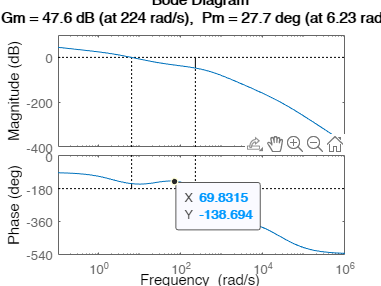


% find GxO and PxO
margin(kappa*ol_stable) % just to look at

[Gm, Pm, PXO, GXO] = margin(ol_stable)

Gm = 40.4217

Pm = 28.1581

PXO = 224.0123

GXO = 16.1287


% normal
% nyqlog(ol_stable)

% visual check for GxO
% nyqlog(Gm*ol_stable)
 
K1 = 1/abs(freqresp(ol_stable, 56.9))

K1 = 6.6689

Number of poles in RHP of open-loop system: 0
Number of net encirclements around the -1 point:   0
=> Number of poles in RHP of closed-loop system:   0
and no closed-loop poles on Im-axis
=> Closed-loop-system is asymptotically stable


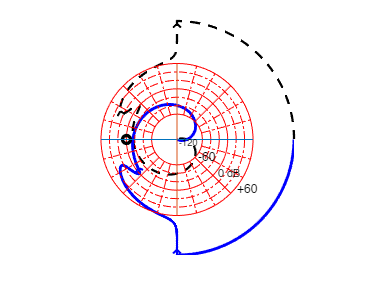


% check that Phase Margin is maximized
nyqlog(K1*ol_stable)

% Step 7: Tune Gain
Ku = margin(D_stable*G*H)

Ku = 6.7989

inc = Ku/100;
Kopt = 1.6997364238235713

Kopt = 1.6997

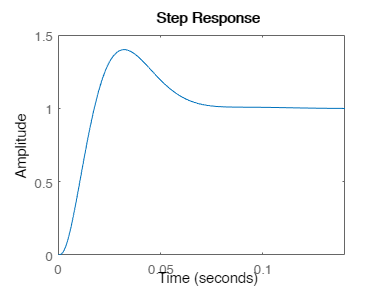

cltf = closed_loop(Kopt, D_stable, G, H);
hold off

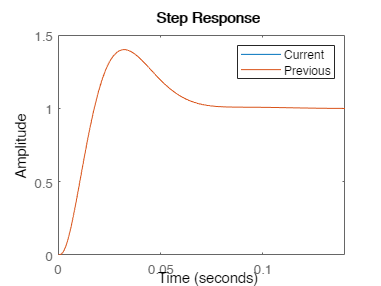

step(cltf)
hold on 
step(last_cltf)
legend("Current", "Previous")
hold off

last_cltf = cltf;

last_cltf = cltf;

% use this to save the value
Kopt_perm = Kopt

Kopt_perm = 1.6997

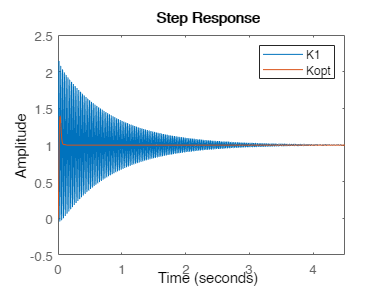

step(closed_loop(K1, D_stable, G,H))
hold on
step(closed_loop(Kopt_perm, D_stable, G, H))
legend("K1", "Kopt")
hold off

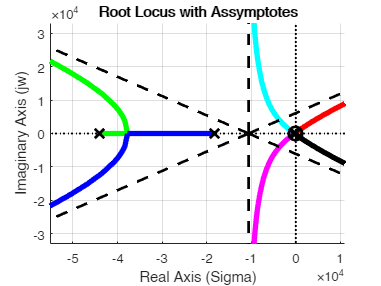

ans = 	1.0e+06 *

   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0001 + 0.0000i  -0.0001 + 0.0000i  -0.0001 + 0.0000i  -0.0001 + 0.0000i  -0.0000 + 0.0001i  -0.0000 + 0.0002i  -0.0000 + 0.0002i  -0.0000 + 0.0002i  -0.0000 + 0.0002i  -0.0000 + 0.0002i  -0.0000 + 0.0002i  -0.0000 + 0.0002i  -0.0000 + 0.0002i  -0.0000 + 0.0002i  -0.0000 + 0.0002i  -0.0000 + 0.0002i  -0.0000 + 0.0002i   0.0000 + 0.0002i   0.0000 + 0.0002i   0.0000 + 0.0002i   0.0000 + 0.0002i   0.0000 + 0.0002i   0.0000 + 0.0002i   0.0000 + 0.0002i   0.0000 + 0.0002i   0.0000 + 0.0002i   0.0000 + 0.0002i   0.0000 + 0.0003i   0.0001 + 0.0004i   0.0002 + 0.0005i   0.0003 + 0.0006i
  -0.0441 + 0.0000i  -0.0441 + 

% Step 7b: Check Root Locus
rla(D_stable*G*H)

% Step 8a: Heuristic Tune
z1 = z_stable

z1 = 22.4013

z2 = z_stable

z2 = 22.4013


K_0  = Kopt

K_0 = 1.6997

Kp_0 = (z1+z2)/(z1*z2)-1/p

Kp_0 = 0.0871

Ki_0 = 1

Ki_0 = 1

Kd_0 = 1/(z1*z2)-(z1+z2)/(p*(z1*z2))+1/(p*p)

Kd_0 = 0.0018


bin = 10;
range = 10;

K_step  = K_0/bin;
Kp_step = Kp_0/bin;
Ki_step = Ki_0/bin;
Kd_step = Kd_0/bin;

K_max  = K_0*range;  K_min  = - K_0;
Kp_max = Kp_0*range; Kp_min = - Kp_0;
Ki_max = Ki_0*range; Ki_min = - Ki_0;
Kd_max = Kd_0*range; Kd_min = - Kd_0;


D_0 = Kp_0+Ki_0/s+(Kd_0*p*s)/(p+s);

hold off

step(closed_loop(K_0,D_0,G,H))
hold off

% Tune
% K_inc  =   0;
% Kp_inc = 0;
% Ki_inc =                 -0.2;
% Kd_inc = 0.01803387068615457;
% 
% K = K_0 + K_inc
% Kp = Kp_0 + Kp_inc
% Ki = Ki_0 + Ki_inc
% Kd = Kd_0 + K_inc 

K  = K_0  *0.75

K = 1.2748

Kp = Kp_0 *0.2

Kp = 0.0174

Ki = Ki_0 *0.5

Ki = 0.5000

Kd = Kd_0 *2.55

Kd = 0.0046


D = Kp+Ki/s+(Kd*p*s)/(p+s)

D =
 
  2.133 s^2 + 8.514 s + 230
  -------------------------
         s^2 + 460 s
 
Continuous-time transfer function.



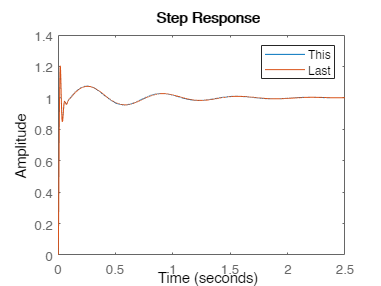


hold off

xfer = closed_loop(K,D,G,H);
step(xfer)
[y, t] = step(xfer);
maxxx = max(y)

maxxx = 1.1850

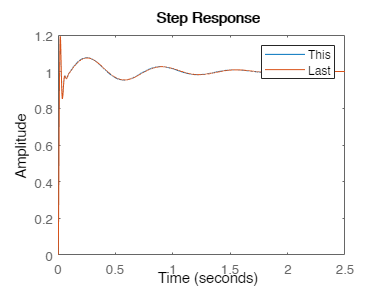

hold on 
step(last)
legend("This", "Last")
hold off

last = xfer;

last = xfer;

stepinfo(y, x, 'RiseTimeLimits', [0 1])

Unrecognized function or variable 'y'.